clc; close all; clear;

inDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/');
saveDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Writing/Figures/simulations_marz/3D/');

% load 
data3D = importfile2([inDir, 'xy14Bdots_1.dat']); % 3D file
data2D = importfile2([inDir, 'xy15Bdots_1.dat']); % 3D file

B_3D = sqrt(data3D(:,end).^2 + data3D(:,end-1).^2 + data3D(:,end-2).^2); 
B_2D = sqrt(data2D(:,end).^2 + data2D(:,end-1).^2 + data2D(:,end-2).^2); 


% Rm for 2D data
rho = data2D(:,2);
Te = data2D(:,3);

load physicalConstants-SI.mat mp mu0
ni = rho / (27 * mp);
addpath(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Other/PlasmaFormulary/'))
F = FundamentalPlasma();

Zbar = F.getZbarTF(13,27,SI2cgs(rho,'Mass Density'),Te);
ne = Zbar .* ni;

eta = F.getParSpitzerRes(Zbar,Te,SI2cgs(ne,'Density')); % Ohm-cm

lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -2.9
lnA = 8.0
lnA = 7.5
lnA = 7.1
lnA = 6.8
lnA = 6.5
lnA = 6.2
lnA = 6.0
lnA = 5.8
lnA = 5.6
lnA = 5.4
lnA = 5.2
lnA = 5.0
lnA = 4.7
lnA = 4.5
lnA = 4.4
lnA = 4.3
lnA = 4.2
lnA = 4.1
lnA = 4.0
lnA = 4.0
lnA = 4.0


eta = eta * 0.01; %Ohm-m

V_2D = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot_rad_tran.txt'));
V_2D = V_2D(:,3);

L = 15e-3;
Rm_2D = V_2D * L ./ (eta / mu0); 

% Rm for 3D data
rho = data3D(:,2);
Te = data3D(:,3);

load physicalConstants-SI.mat mp mu0
ni = rho / (27 * mp);
addpath(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Other/PlasmaFormulary'))
F = FundamentalPlasma();

Zbar = F.getZbarTF(13,27,SI2cgs(rho,'Mass Density'),Te);
ne = Zbar .* ni;

eta = F.getParSpitzerRes(Zbar,Te,SI2cgs(ne,'Density')); % Ohm-cm

lnA = 5.7
lnA = 5.6
lnA = 5.3
lnA = 5.1
lnA = 4.8
lnA = 4.6
lnA = 4.5
lnA = 4.4
lnA = 4.2
lnA = 4.1
lnA = 4.1


eta = eta * 0.01; %Ohm-m

V_3D = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/V_at_bdot_3D.txt')); 
L = 15e-3;
Rm_3D = V_3D' * L ./ (eta / mu0); 

% 2D sim; rad loss

data = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot.txt'));
B = data(:,2);

rho = data(:,end);
Te = data(:,end-1);

load physicalConstants-SI.mat mp mu0
ni = rho / (27 * mp);
addpath(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Other/PlasmaFormulary'))
F = FundamentalPlasma();

Zbar = F.getZbarTF(13,27,SI2cgs(rho,'Mass Density'),Te);
ne = Zbar .* ni;

eta = F.getParSpitzerRes(Zbar,Te,SI2cgs(ne,'Density')); % Ohm-cm

lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = 8.7
lnA = 8.0
lnA = 7.5
lnA = 7.0
lnA = 6.7
lnA = 6.4
lnA = 6.2
lnA = 5.9
lnA = 5.8
lnA = 5.6
lnA = 5.4
lnA = 5.2
lnA = 5.1
lnA = 4.9
lnA = 4.8
lnA = 4.7
lnA = 4.5
lnA = 4.4
lnA = 4.2
lnA = 4.1
lnA = 4.1
lnA = 4.0
lnA = 4.0


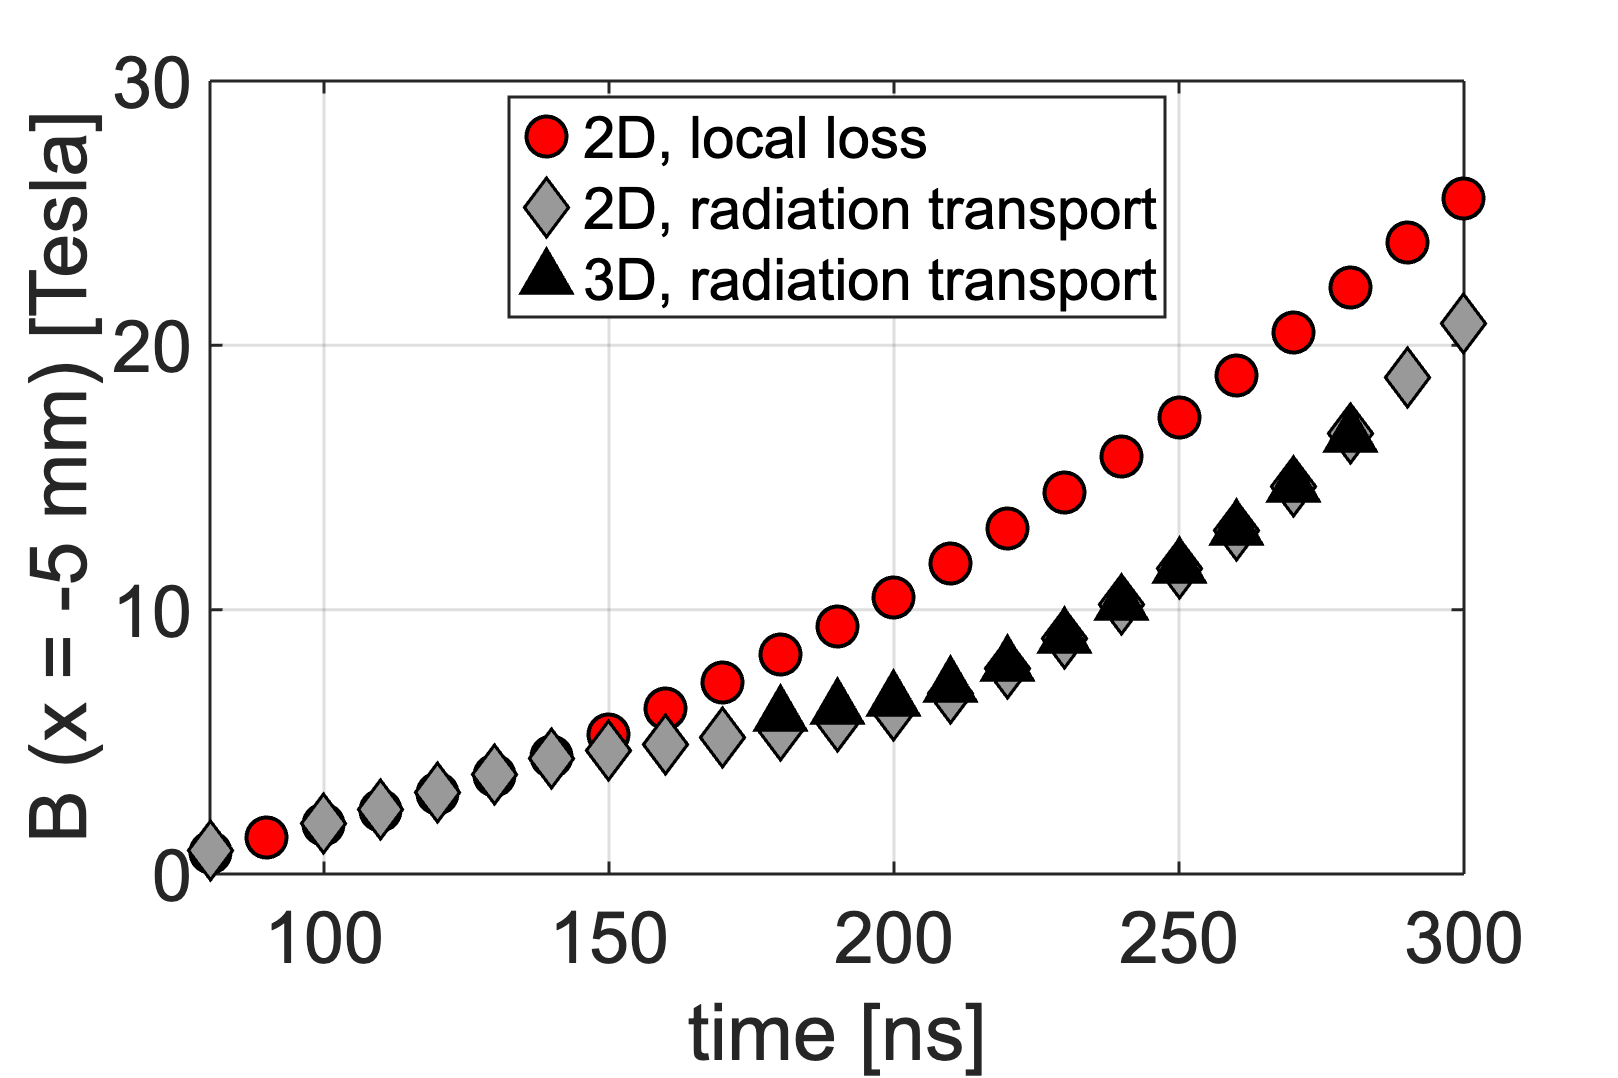

eta = eta * 0.01; %Ohm-m

V = data(:,3); 
L = 15e-3;
Rm_rad_loss = V * L ./ (eta / mu0); 

% % 2D sim; rad tran
% 
% data2 = dlmread('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot_rad_tran.txt');
% B2 = data2(:,2);
% 
% rho = data2(:,end);
% Te = data2(:,end-1);
% 
% load physicalConstants-SI.mat mp mu0
% ni = rho / (27 * mp);
% addpath('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Other/PlasmaFormulary')
% F = FundamentalPlasma();
% 
% Zbar = F.getZbarTF(13,27,SI2cgs(rho,'Mass Density'),Te);
% ne = Zbar .* ni;
% 
% eta = F.getParSpitzerRes(Zbar,Te,SI2cgs(ne,'Density')); % Ohm-cm
% eta = eta * 0.01; %Ohm-m
% 
% V = data2(:,3); 
% L = 15e-3;
% Rm_2 = V * L ./ (eta / mu0); 



figure

mkr = 20;
plot(data(:,1),B,'o',LineWidth=2,DisplayName='2D, local loss',markersize=mkr,color='k',MarkerFaceColor='red'); hold on;

plot(data2D(:,1),B_2D,'D',LineWidth=2,DisplayName='2D, radiation transport',markersize=mkr,...
    color='k',MarkerFaceColor=[0.6,0.6,0.6]); hold on;

plot(data3D(:,1),B_3D,'^',LineWidth=3,DisplayName='3D, radiation transport',markersize=mkr,...
    color='k',MarkerFaceColor='k'); hold on;


% plot(data2(:,1),B2,'o',LineWidth=3,DisplayName='3D, multi-group transport',markersize=mkr,...
%     color='k',MarkerFaceColor='g'); hold on;



ylabel('B (x = -5 mm) [Tesla]');
xlabel('time [ns]')

grid on;
formatPlots(900,1.5);
legend('Location','north','box','on')
% legend('off');
set(gca,'FontSize',36); xlim([80,300])
saveas(gcf,[saveDir 'B.png']);

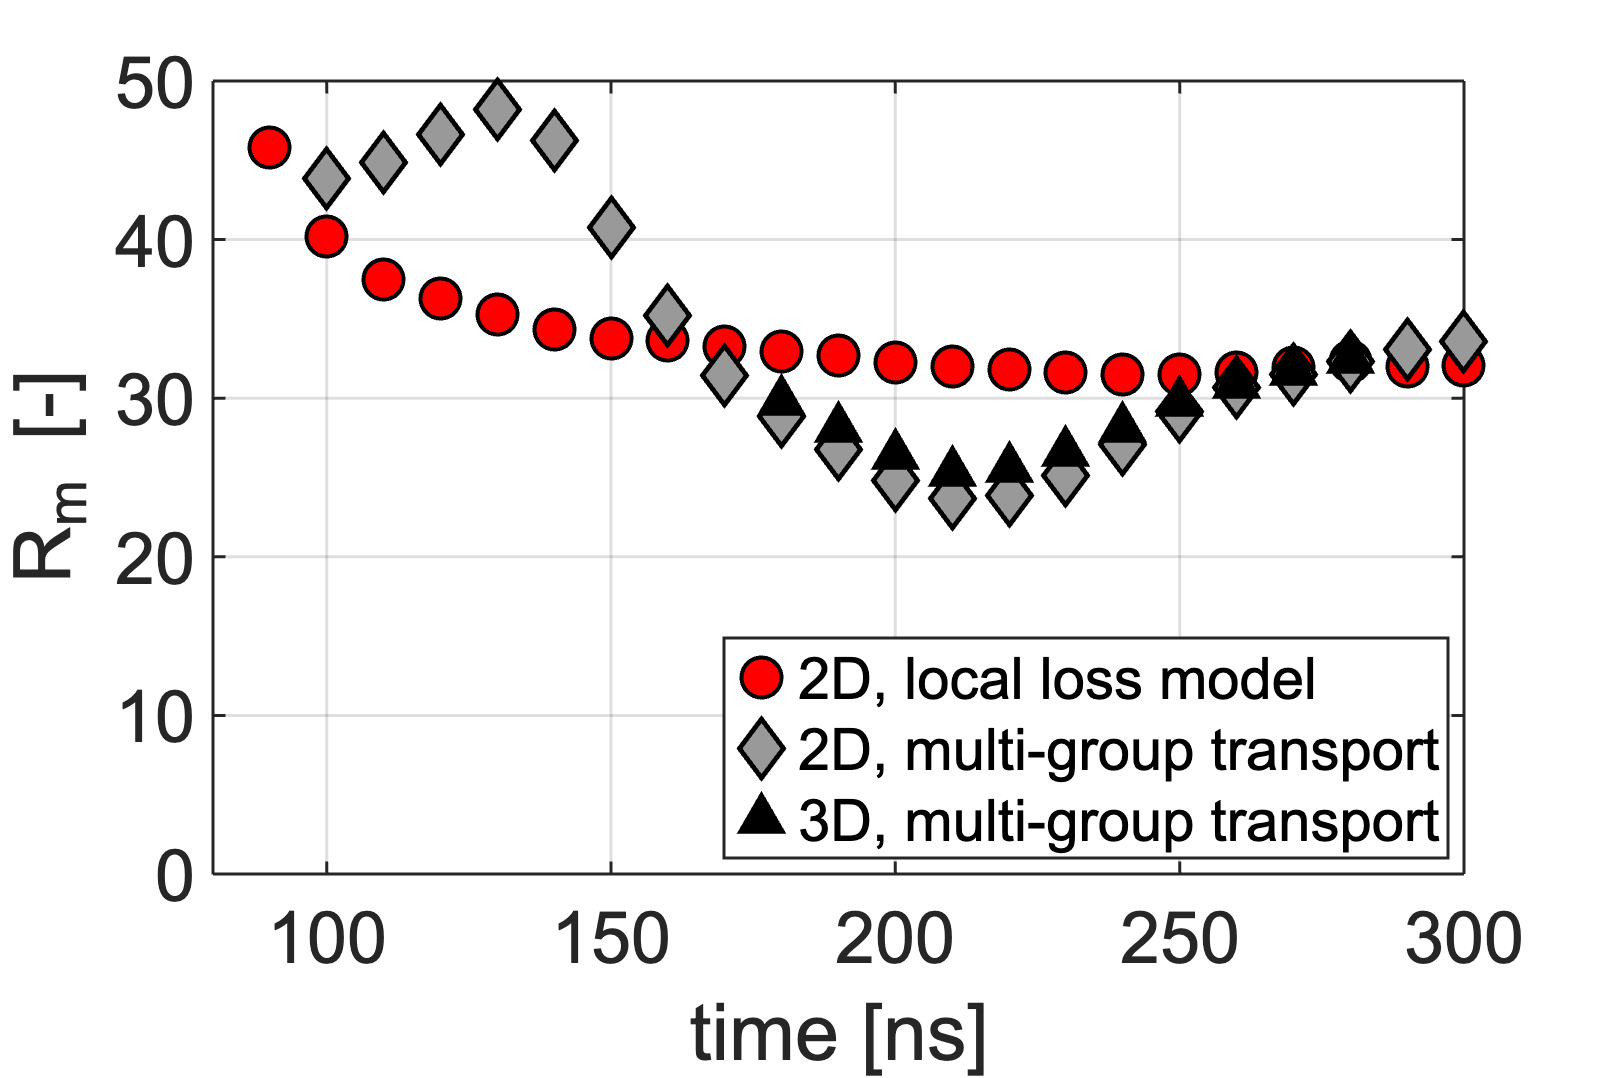



figure

plot(data(:,1),Rm_rad_loss,'o',color='k',MarkerFaceColor='red',LineWidth=2,DisplayName='2D, local loss model',markersize=mkr); hold on;

plot(data2D(:,1),Rm_2D,'D',color='k',MarkerFaceColor=[0.6,0.6,0.6],LineWidth=3,DisplayName='2D, multi-group transport',markersize=mkr); hold on;

plot(data3D(:,1),Rm_3D,'^',color='k',MarkerFaceColor='k',LineWidth=1,DisplayName='3D, multi-group transport',markersize=mkr);

% plot(data2(:,1),Rm_2,'o',color='g',MarkerFaceColor='k',LineWidth=3,DisplayName='3D, multi-group transport',markersize=mkr);

xlabel('time [ns]');

ylabel('R_m [-]');

xlabel('time [ns]')

grid on; ylim([0,50]); xlim([0,300])
formatPlots(900,1.5);
legend('location','southeast','box','on')
set(gca,'FontSize',36); xlim([80,300])

saveas(gcf,[saveDir 'Rm.png']); 

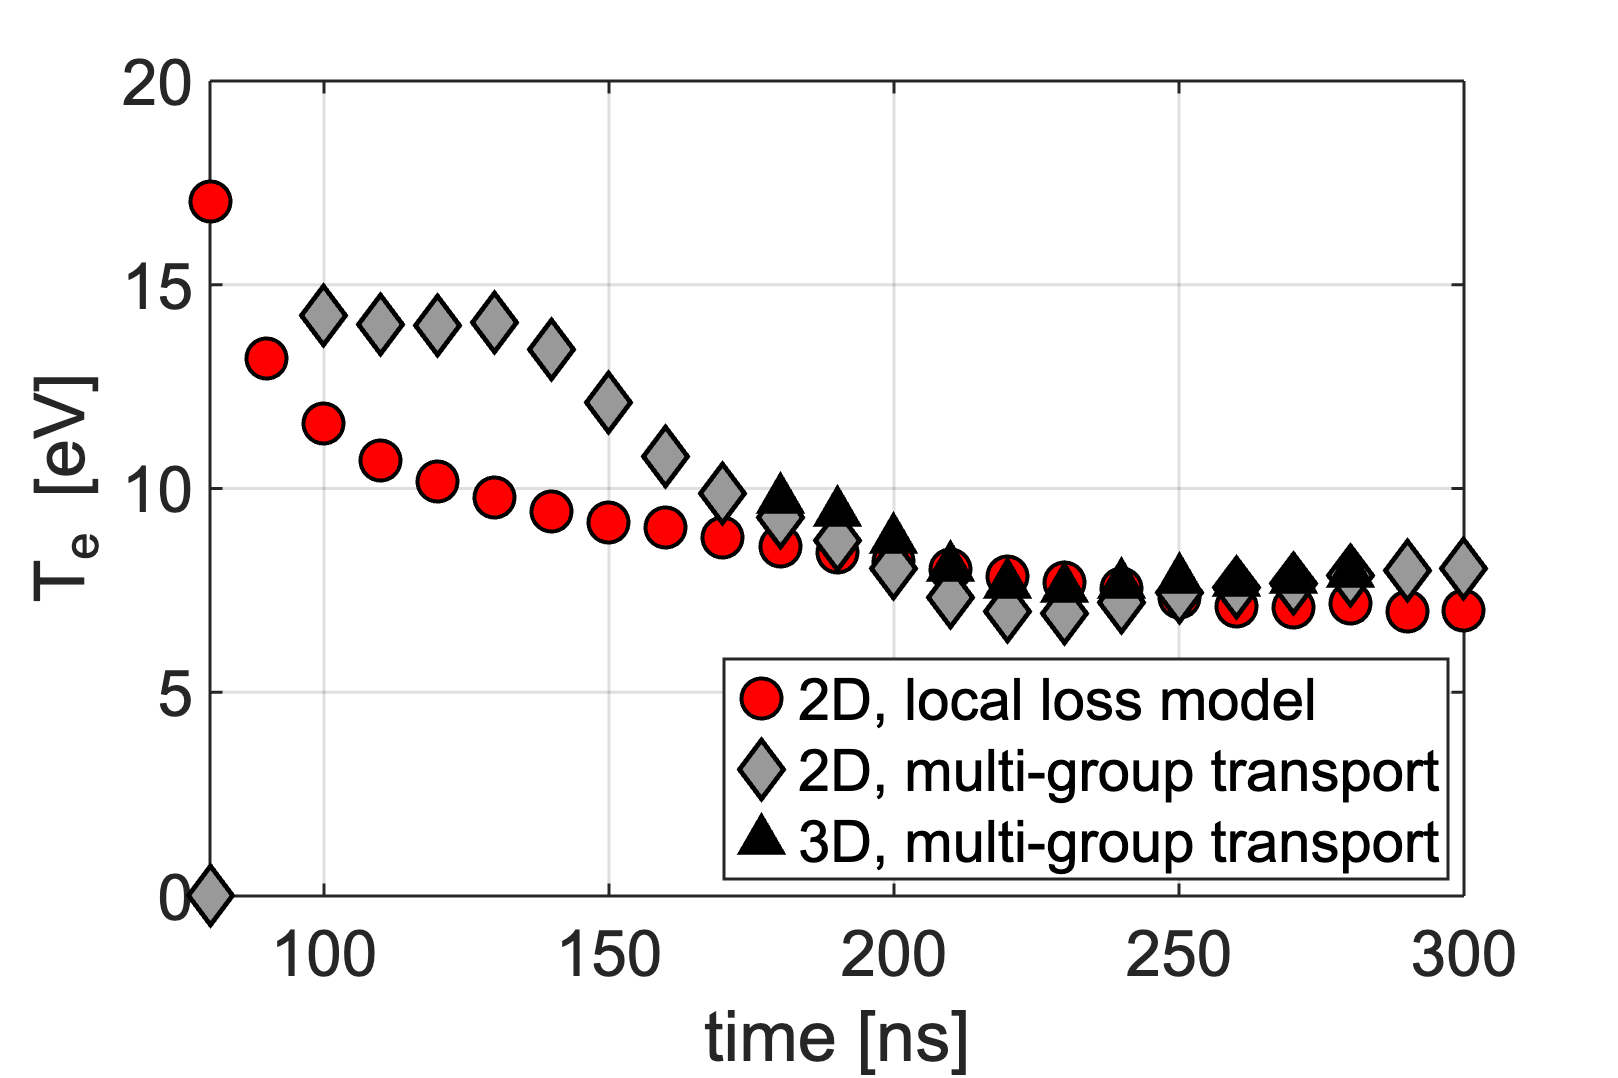


figure

plot(data(:,1),data(:,end-1),'o',color='k',MarkerFaceColor='red',LineWidth=2,DisplayName='2D, local loss model',markersize=mkr); hold on;

plot(data2D(:,1),data2D(:,3),'D',color='k',MarkerFaceColor=[0.6,0.6,0.6],LineWidth=3,DisplayName='2D, multi-group transport',markersize=mkr); hold on;

plot(data3D(:,1),data3D(:,3),'^',color='k',MarkerFaceColor='k',LineWidth=1,DisplayName='3D, multi-group transport',markersize=mkr);

xlabel('time [ns]');

ylabel('T_e [eV]');

xlabel('time [ns]')

grid on; ylim([0,20]); xlim([80,300])
formatPlots(900,1.5);
legend('location','southeast','box','on');



% compare eta


load physicalConstants-SI.mat mu0 

fname= checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/eta_at_bdot.txt');
eta = dlmread(fname) / mu0; % ^2/s

data = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot.txt'));


rho = data(:,end);
Te = data(:,end-1);

load physicalConstants-SI.mat mp mu0
ni = rho / (27 * mp);
addpath(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Other/PlasmaFormulary'))
F = FundamentalPlasma();

Zbar = F.getZbarTF(13,27,SI2cgs(rho,'Mass Density'),Te);
ne = Zbar .* ni;

eta2 = F.getParSpitzerRes(Zbar,Te,SI2cgs(ne,'Density')); % Ohm-cm

lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = 8.7
lnA = 8.0
lnA = 7.5
lnA = 7.0
lnA = 6.7
lnA = 6.4
lnA = 6.2
lnA = 5.9
lnA = 5.8
lnA = 5.6
lnA = 5.4
lnA = 5.2
lnA = 5.1
lnA = 4.9
lnA = 4.8
lnA = 4.7
lnA = 4.5
lnA = 4.4
lnA = 4.2
lnA = 4.1
lnA = 4.1
lnA = 4.0
lnA = 4.0


eta2 = 1 * eta2 * 0.01 / mu0; %m^2/s

eta_EH = []; % Ohm-m
for ii = 1:length(ne)
    eta_EH = [eta_EH; getEtaPar(ne(ii),Zbar(ii),Te(ii))];
end

'getEtaPar' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Bdot

Change the MATLAB current folder or add its folder to the MATLAB path.

eta_EH = eta_EH / mu0; % m^2/s


figure
plot(data(:,1),eta,LineWidth=3,DisplayName='output'); hold on;
plot(data(:,1),eta2,LineWidth=3,DisplayName='calculated (Spitzer)'); hold on;
plot(data(:,1),eta_EH,LineWidth=3,DisplayName='calculated (EH)'); hold on;
xlabel('time [ns]'); ylabel('\eta [m^2/s]')
formatPlots(900,1.5);
grid on; xlim([100,300])


% 2D rad. tran. 1 mm from wires

fname = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\sims\data_at_bdot_x=1mm.txt');
% fname = 'data_at_bdot_x=-5mm.txt'
data = dlmread(fname); 

% 2D sim; rad tran


rho = data(:,end);
Te = data(:,end-1);

addpath(checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN\Codes\Other\PlasmaFormulary'))
load physicalConstants-SI.mat mp mu0
ni = rho / (27 * mp);

F = FundamentalPlasma();

Zbar = F.getZbarTF(13,27,SI2cgs(rho,'Mass Density'),Te);
ne = Zbar .* ni;

eta = F.getParSpitzerRes(Zbar,Te,SI2cgs(ne,'Density')); % Ohm-cm

lnA = -1.5
lnA = -1.5
lnA = 9.1
lnA = 7.6
lnA = 6.6
lnA = 6.1
lnA = 5.8
lnA = 5.5
lnA = 5.2
lnA = 4.7
lnA = 4.3
lnA = 4.1
lnA = 4.1
lnA = 4.0
lnA = 3.9
lnA = 4.0
lnA = 4.0
lnA = 3.9
lnA = 3.9
lnA = 3.9
lnA = 3.8
lnA = 3.8
lnA = 3.8
lnA = 3.8
lnA = 3.8
lnA = 3.7


eta = eta * 0.01; %Ohm-m

V = data(:,3); 
L = 15e-3;
Rm = V .* L ./ (eta / mu0); 

figure
plot(data(:,1),Rm,'ok',markersize=16,DisplayName='1 mm',markerfacecolor='r'); hold on;
xlabel('time'); ylabel('Rm'); formatPlots(900,1.5);


% 2D sim; rad tran

data2 = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot_rad_tran.txt'));

rho = data2(:,end);
Te = data2(:,end-1);

load physicalConstants-SI.mat mp mu0
ni = rho / (27 * mp);
F = FundamentalPlasma();

Zbar = F.getZbarTF(13,27,SI2cgs(rho,'Mass Density'),Te);
ne = Zbar .* ni;

eta = F.getParSpitzerRes(Zbar,Te,SI2cgs(ne,'Density')); % Ohm-cm

lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = -1.5
lnA = 8.8
lnA = 7.9
lnA = 7.5
lnA = 7.1
lnA = 6.8
lnA = 6.5
lnA = 6.2
lnA = 6.0
lnA = 5.8
lnA = 5.6
lnA = 5.4
lnA = 5.2
lnA = 4.9
lnA = 4.7
lnA = 4.5
lnA = 4.4
lnA = 4.3
lnA = 4.2
lnA = 4.1
lnA = 4.0
lnA = 4.0
lnA = 4.0


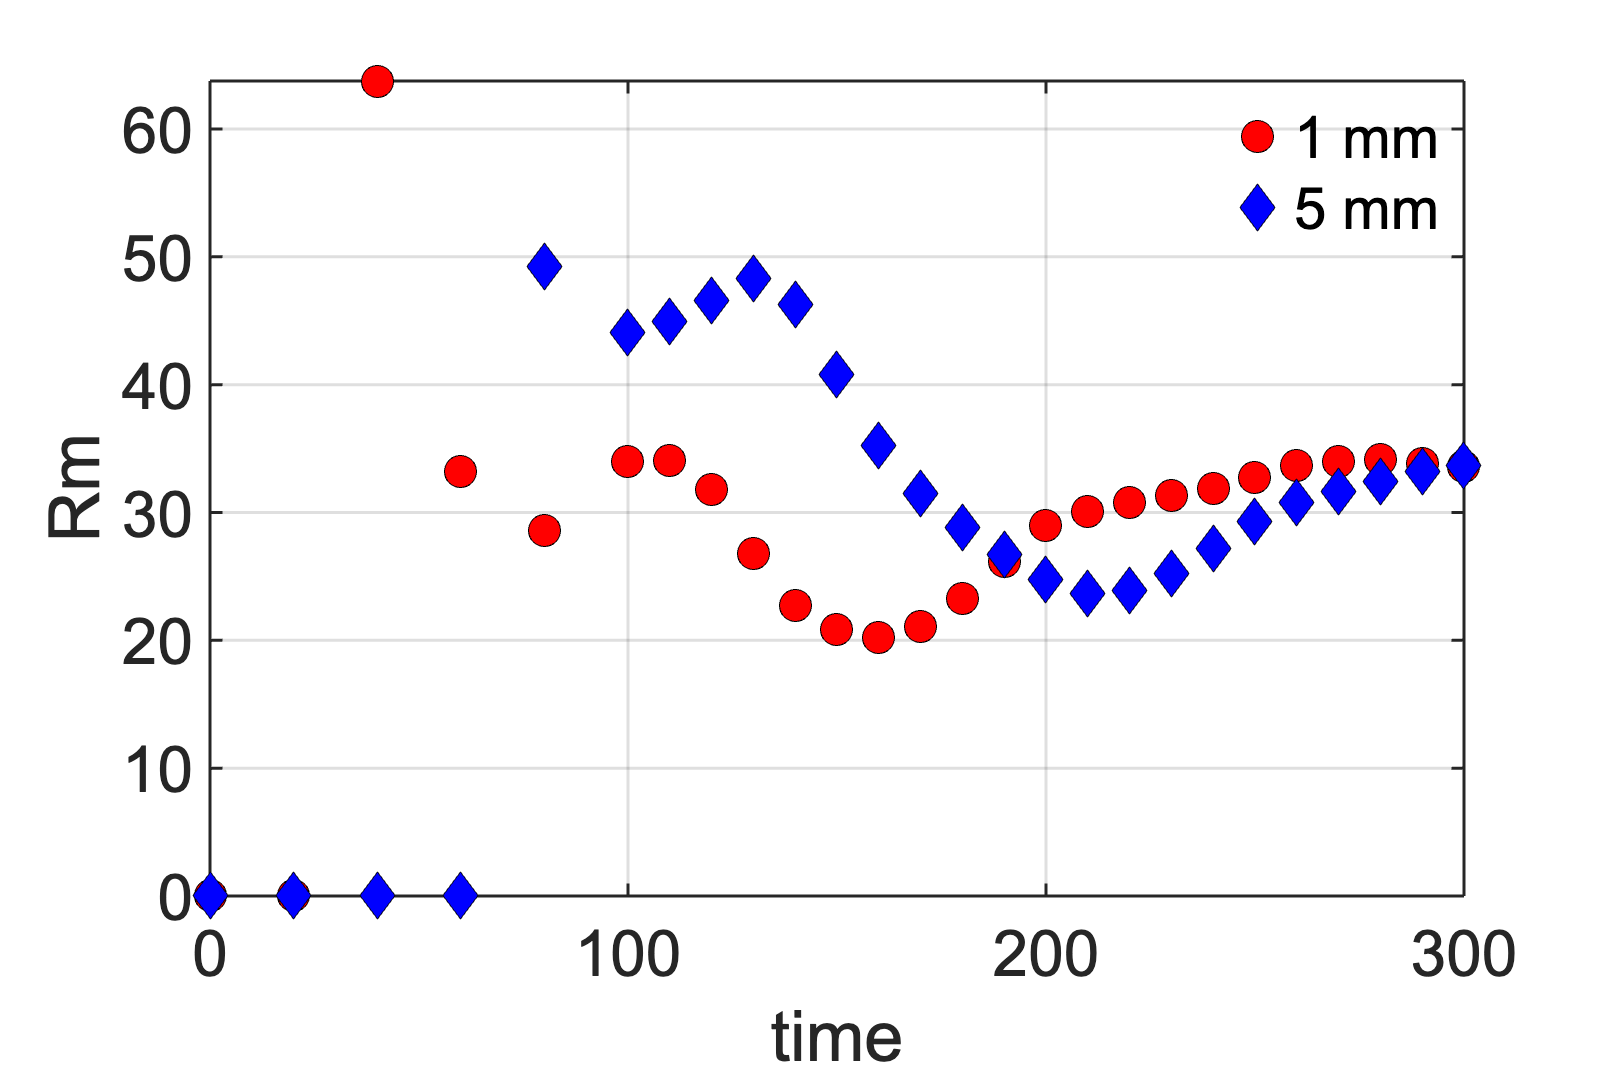

eta = eta * 0.01; %Ohm-m

V = data2(:,3); 
L = 15e-3;
Rm_2 = V * L ./ (eta / mu0); 

plot(data2(:,1),Rm_2,'Dk',markersize=16,DisplayName='5 mm',markerfacecolor='b'); hold on;
grid on;

% Compare rho

data2 = dlmread('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot_rad_tran.txt');
rho = data2(:,end);


figure
plot(data2(:,1),rho,'kD',markersize=16,MarkerFaceColor='r',DisplayName='2D, Multi-group transport'); hold on;


data = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot.txt'));


rho = data(:,end);
plot(data(:,1),rho,'ko',markersize=16,MarkerFaceColor='b',DisplayName='2D, local loss'); hold on;

xlabel('time [ns]');
ylabel('Density [kg/m^3]');
formatPlots(900,1.5);
grid on;
xlim([100,300])

% Compare V



data2 = dlmread('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot_rad_tran.txt');
V = data2(:,3);



figure
plot(data2(:,1),V/1e3,'kD',markersize=16,MarkerFaceColor='r',DisplayName='2D, Multi-group transport'); hold on;


data = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot.txt'));


V = data(:,3);

plot(data(:,1),V/1e3,'ko',markersize=16,MarkerFaceColor='b',DisplayName='2D, local loss'); hold on;

xlabel('time [ns]');
ylabel('V [km/s]');
formatPlots(900,1.5);
grid on;
xlim([100,300])
% Compare rho * V^2

% Compare V



data2 = dlmread('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot_rad_tran.txt');
V = data2(:,3);
rho = data2(:,end);


figure
plot(data2(:,1),rho.*V.^2,'kD',markersize=16,MarkerFaceColor='r',DisplayName='2D, Multi-group transport'); hold on;


data = dlmread(checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/data_at_bdot.txt'));


V = data(:,3);
rho = data(:,end);
plot(data(:,1),rho.*V.^2,'ko',markersize=16,MarkerFaceColor='b',DisplayName='2D, local loss'); hold on;

xlabel('time [ns]');
ylabel('Kinetic pressure [Pa]');
formatPlots(900,1.5);
grid on;
xlim([100,300])


function xy14Bdots1 = importfile2(filename, dataLines)
%IMPORTFILE2 Import data from a text file
%  XY14BDOTS1 = IMPORTFILE2(FILENAME) reads data from text file FILENAME
%  for the default selection.  Returns the numeric data.
%
%  XY14BDOTS1 = IMPORTFILE2(FILE, DATALINES) reads data for the
%  specified row interval(s) of text file FILENAME. Specify DATALINES as
%  a positive scalar integer or a N-by-2 array of positive scalar
%  integers for dis-contiguous row intervals.
%
%  Example:
%  xy14Bdots1 = importfile2("/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/sims/xy14Bdots_1.dat", [1, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 02-Aug-2023 19:10:26

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [1, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
xy14Bdots1 = readtable(filename, opts);

%% Convert to output type
xy14Bdots1 = table2array(xy14Bdots1);
end